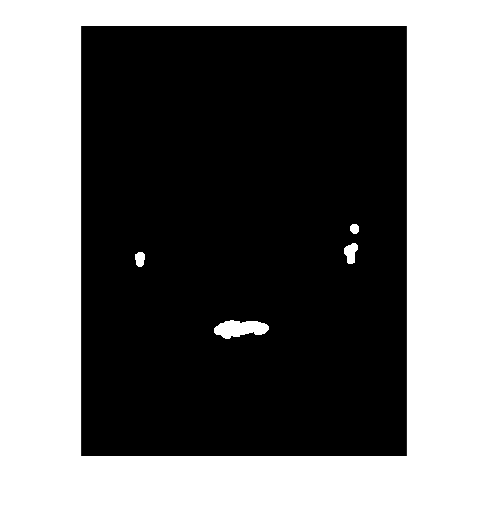

img = imread("../db/DB1/db1_10.jpg");
hybrid_mask = hybrid(img);


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask(eyes,face_mask);

imshow(eye_mask)
imshow(hybrid_mask)

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask);


[indexX,indexY] = eye_index(hybrid_mask)


indexX =

     []


indexY =

     []



mouth_center = [x, y]; % replace with actual coordinates
[eye1 , eye2] = findEyePair(indexX,indexY,mouth_center)


eye1 =

     []


eye2 =

     []



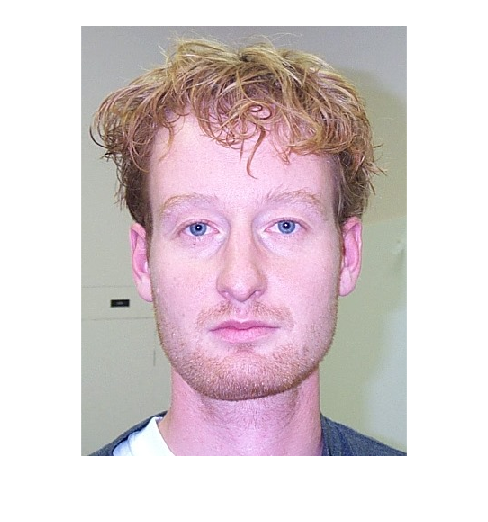


imshow(img)
hold on;

viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

Index exceeds the number of array elements. Index must not exceed 0.